# Hodgkin-Huxley Model Simulation

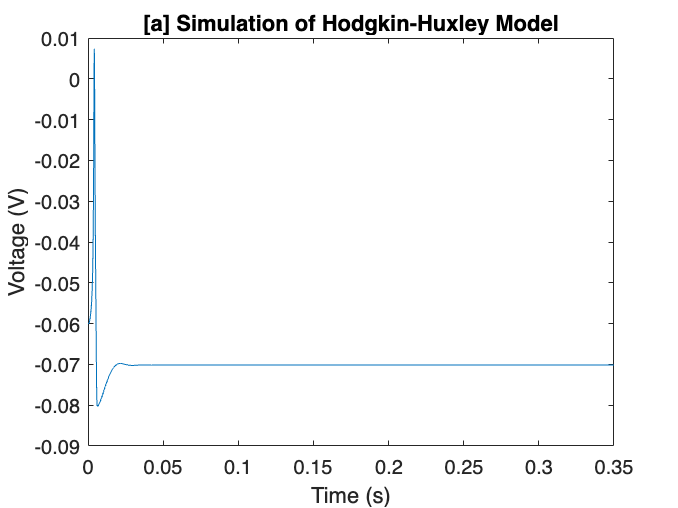

% Declare Global Parameter Values
Gl = 30e-9; % in Siemens
GNa = 12e-6; % in Siemens
Gk = 3.6e-6; % in Siemens
ENa = 45e-3; % in Volts (V)
Ek = -82e-3; % in V
El = -60e-3; % in V
Cm = 100e-12; % in Farads

% Set up time vector
t0 = 0;
dt = 0.1e-3;
t_max = .35; % in seconds
tvec = t0:dt:t_max;

% Create membrane potential vector
Vm = zeros(size(tvec));

% Create gating variable vectors (to be updated with each new Vm)
m = zeros(size(tvec));
h = zeros(size(tvec));
n = zeros(size(tvec));

% Set initial conditions
Vm(1) = El;
Iapp = 0; % current set to 0

% Run Euler's Method
for i = 2:length(tvec)
    dVdt = (1/Cm)*(Gl*(El-Vm(i-1)) + GNa*(m(i-1)^3)*h(i-1)*(ENa - Vm(i-1))+ Gk*(n(i-1)^4)*(Ek-Vm(i-1)) + Iapp); %compute dVdt
    Vm(i) = EM(Vm(i-1), dVdt, dt); % call function EM (Euler's Method) to update Vm(i)
    dmdt = alphaM(Vm(i-1))*(1-m(i-1)) - betaM(Vm(i-1))*m(i-1); % compute dmdt
    m(i) = EM(m(i-1), dmdt, dt);   % call EM to update m(i)
    dhdt = alphaH(Vm(i-1))*(1-h(i-1)) - betaH(Vm(i-1))*h(i-1);
    h(i) = EM(h(i-1), dhdt, dt);
    dndt = alphaN(Vm(i-1))*(1-n(i-1)) - betaN(Vm(i-1))*n(i-1);
    n(i) = EM(n(i-1), dndt, dt);
end

% Plot figure
figure;
plot(tvec, Vm)
xlabel('Time (s)')
xlim([0 0.35]);
ylabel('Voltage (V)')
title('Simulation of Hodgkin-Huxley Model')

function y = EM(a, b, c) %Euler's Method Function
y = a + b*c;
end
% These alpha and beta functions calcuate the rate constants and take the
% current voltage value as the argument and calculate the corresponding
% rate constant, updated with each iteration of the Euler's Method
% simulation.

function y = alphaM(x)
if exp(100*(-x-0.045))-1 == 0 % Checks for division by zero to prevent
errors
y = 0;
else
y = ((10^5)*(-x-0.045))/(exp(100*(-x-0.045))-1);
end
end
function y = betaM(x)
y = 4*(10^3)*exp((-x-0.070)/0.018);
end
function y = alphaH(x)
y = 70*exp(50*(-x-0.070));
end
function y = betaH(x)
y = 10^3/(1 + exp(100*(-x-0.040)));
end
function y = alphaN(x)
if exp(100*(-x-0.060))-1 == 0
y = 0;
else
y = ((10^4)*(-x-0.060))/(exp(100*(-x-0.060))-1);
end
end
function y = betaN(x)
y = 125*exp((-x-0.070)/0.08);
end